# DSP Project 1 - Part 2

#### Filter a Noisy Quail Call signal using a Bandpass filter 

#### Retrieve the time domain,spectrogram, and fft graphs of the original signal and the filtered signal

#### Group Members:

- Farshad Bolouri

- Brennae Stinson

- Anindita Das

## Introduction

A data acquisition system consisting of four microphones, placed near several quail habitats, documented calls from these species over time. Each of these microphones recorded calls which are audible through .wav files. The signals retrieved from the data acquisition system almost always contain background noise from the quail environments such as trees rustling, other animals, and wind. The objective of our designed filtering system was to reduce the background noise from the signal so the call would be more apparent to detect both audibly and visually. The following report details intermediate results of this filtering and analysis of the results obtained from the filter. This analysis includes retrieving and inspecting the time and frequency domain graphs, and the resulting .wav files of the signals.

clear
close all

% Variables for spectrogram function
F = 1000:10:3200;
window = 24000*0.04;
noverlap = round(0.8*window);

### Loading and Visualzing the original noisy signal

Let us first define a noisy signal and a clean signal. As mentioned above, the background noise is present in almost all audio files. The reason behind this is that some quails are closer to the microphones while making the calls, hence are more apparent in a recording (the value of their frequency-domain component is higher), whereas, other quail calls made from a greater distance, making the background noise is much more prominent when the quail calls are acquired from a greater distance. Therefore, for the purposes of this project, we will define a noisy signals as ones where the quail calls were far from the microphones and a clean signals as ones where the quail calls were close to the microphone.

[noisySig, fs] = audioread('noisySig.wav');
noisyInfo = audioinfo('noisySig.wav')

noisyInfo = struct with fields:
             Filename: 'C:\Users\farsh\Documents\GitHub\Digital-Signal-Processing\Project1\noisySig.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 240001
             Duration: 10.0000
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


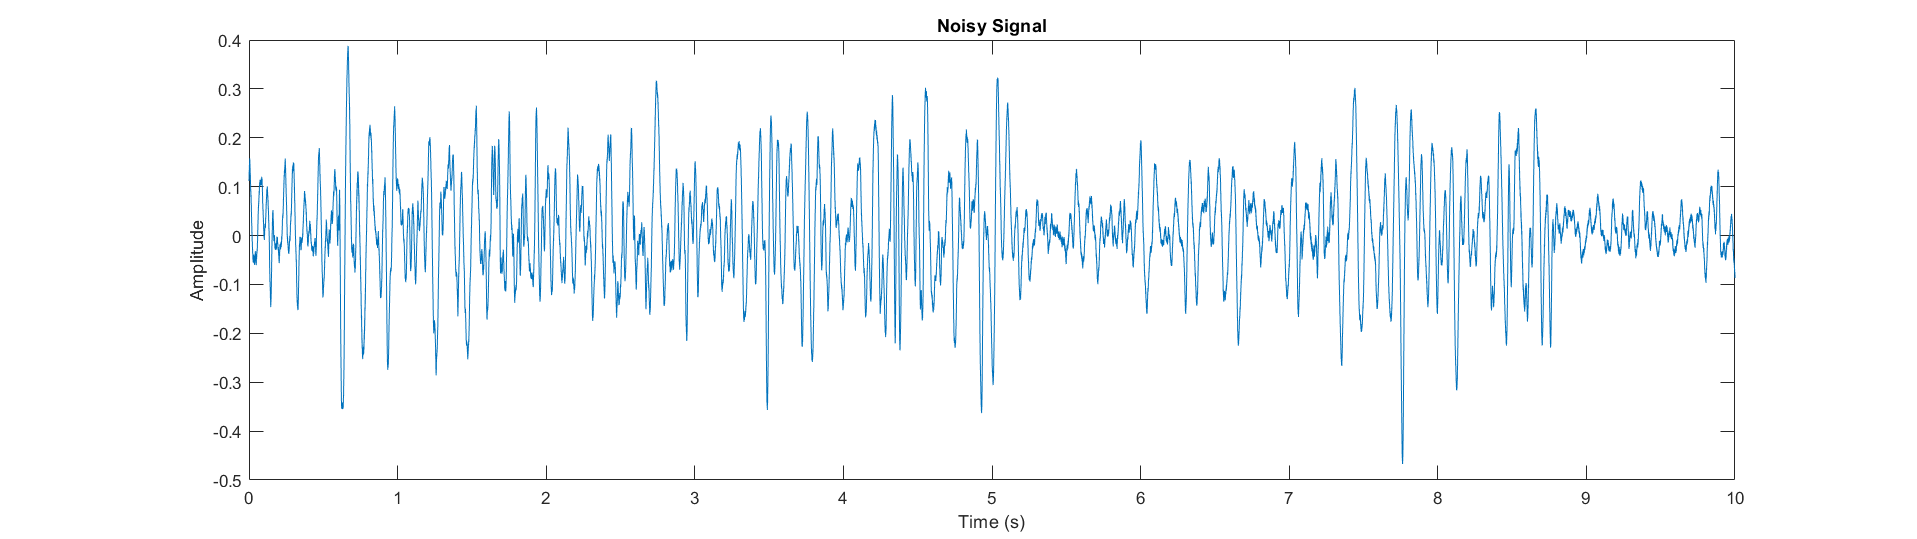

timeNoisy = linspace(0, noisyInfo.Duration, noisyInfo.TotalSamples);
h = figure;
plot(timeNoisy, noisySig)
title('Noisy Signal')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .5]);

As you can clearly see, it is very difficult to tell that there are any quail calls present in the signal.

Now let's listen to this signal:

*(If you would prefer to not listen to this audio file, don't run this section or comment it out :) )*

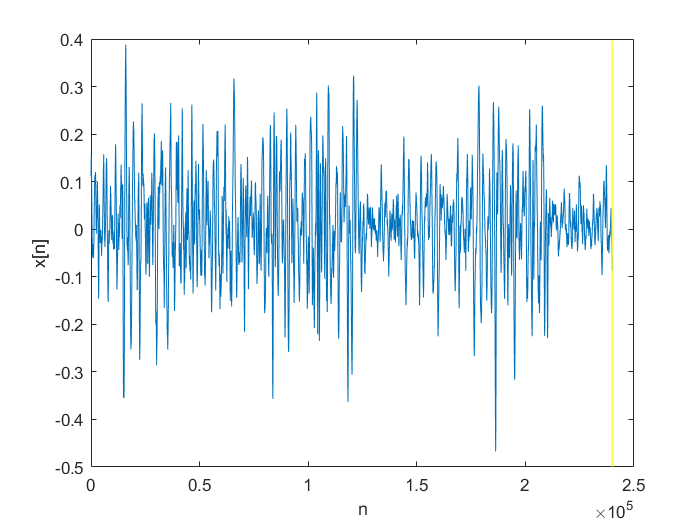

player = audioplayer(noisySig,fs);
figure
plot(noisySig)
xlabel('n')
ylabel('x[n]')
pause(2)
hold on
Bar = xline(0,'Color','yellow','LineWidth',1.5);
play(player);
for i = 1:length(noisySig)/2400
     set(Bar,'Value',Bar.Value+2400);
     pause(.1);
end

As demonstrated here, you can hear the calls but with a lot of noise.

As explained in the previous section,

The reason we cannot see the calls in the audio file is due to quails being far away from the microphone.

Here's another signal with the same background noise (minutes after the previous signal was recorded):

[cleanSig, fs] = audioread('cleanSig.wav');
cleanInfo = audioinfo('cleanSig.wav')

cleanInfo = struct with fields:
             Filename: 'C:\Users\farsh\Documents\GitHub\Digital-Signal-Processing\Project1\cleanSig.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 240000
             Duration: 10
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


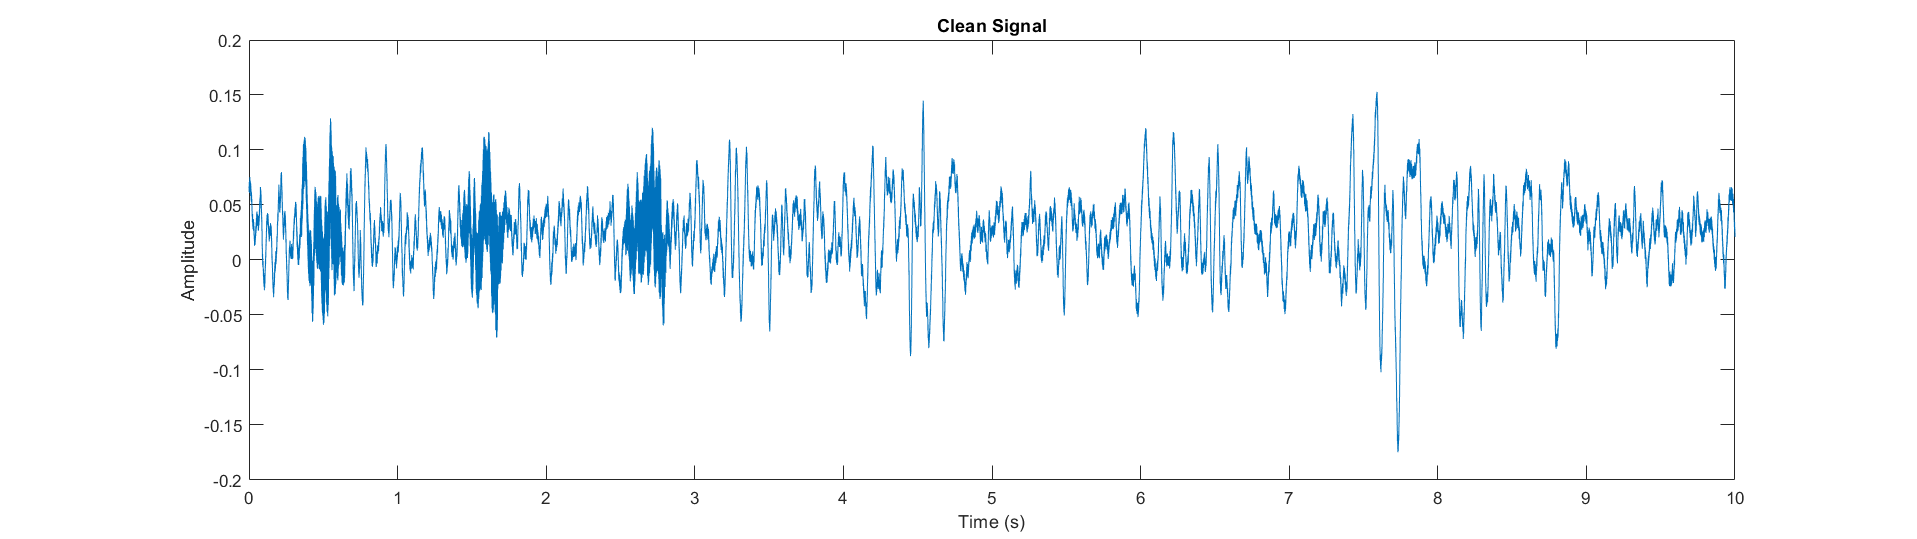

timeClean = linspace(0, cleanInfo.Duration, cleanInfo.TotalSamples);
h = figure;
plot(timeClean, cleanSig)
title('Clean Signal')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .5]);

Here, you can see the three quail calls in the beginning of the audio file.

Now let's listen to this signal:

*(If you would prefer to not listen to this audio file, don't run this section or comment it out :) )*

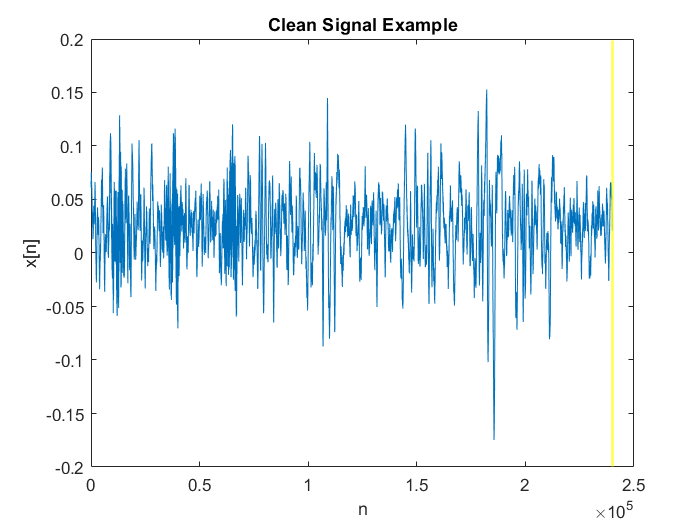

player2 = audioplayer(cleanSig,fs);
figure
plot(cleanSig)
title('Clean Signal Example')
xlabel('n')
ylabel('x[n]')
pause(2)
hold on
Bar = xline(0,'Color','yellow','LineWidth',1.5);
play(player2);
for i = 1:length(cleanSig)/2400
     set(Bar,'Value',Bar.Value+2400);
     pause(.1);
end

You can definitely hear them much louder while still hearing the same background noise.

In this case, the quails were much closer to the microphone and thats why you can hear and see the calls much clearer.

### Signals in Frequency Domain

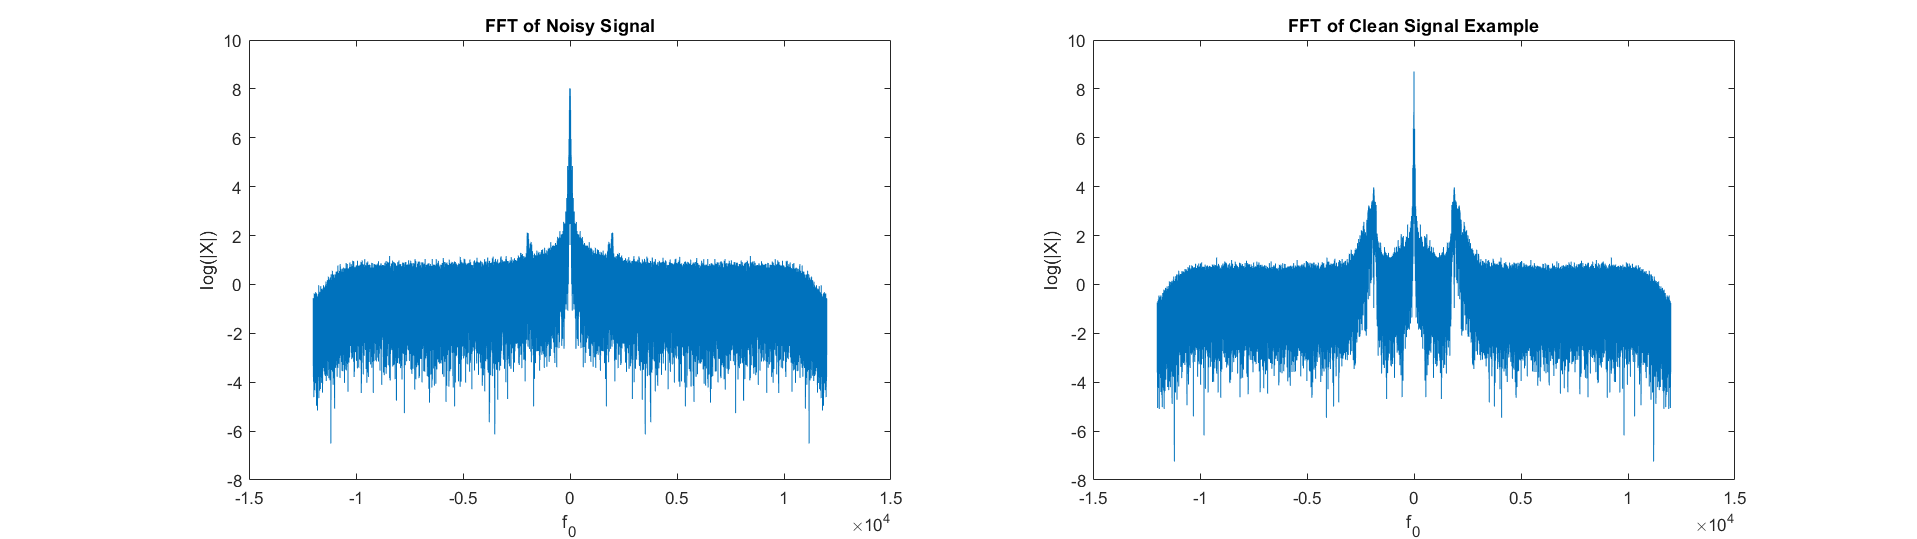

h = figure;
subplot(1,2,1)
noisyFFT = log(abs (fftshift(fft(noisySig))));                  % Zero-Centered FFT
f01 = (-noisyInfo.TotalSamples/2:noisyInfo.TotalSamples/2-1)...
    /noisyInfo.TotalSamples*fs;                                 % Zero-Centered Frequency Range
plot(f01, noisyFFT)
title('FFT of Noisy Signal');
ylabel('log(|X|)')
xlabel('f_{0}');
subplot(1,2,2)
cleanFFT = log(abs (fftshift(fft(cleanSig))));                  % Zero-Centered FFT
f02 = (-cleanInfo.TotalSamples/2:cleanInfo.TotalSamples/2-1)...
    /cleanInfo.TotalSamples*fs;                                 % Zero-Centered Frequency Range
plot(f02, cleanFFT)
title('FFT of Clean Signal Example');
ylabel('log(|X|)')
xlabel('f_{0}');
set(h,'Units','normalized','Position',[0 0 1 .5]); 

The two peaks at the sides of the DC offset are corresponding to the Quail Calls. You can see how the two peaks are having a greater magnitude in the clean signal as the quails were closer to the microphone.

### Quail Call Characteristics

In order to find the bandwidth we started with analyzing the characteristics of the quail calls. Here's an example of a clean quail call:

[quailCall, ~] = audioread("quailCall.wav");
quailInfo = audioinfo("quailCall.wav")

quailInfo = struct with fields:
             Filename: 'C:\Users\farsh\Documents\GitHub\Digital-Signal-Processing\Project1\quailCall.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 25001
             Duration: 1.0417
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


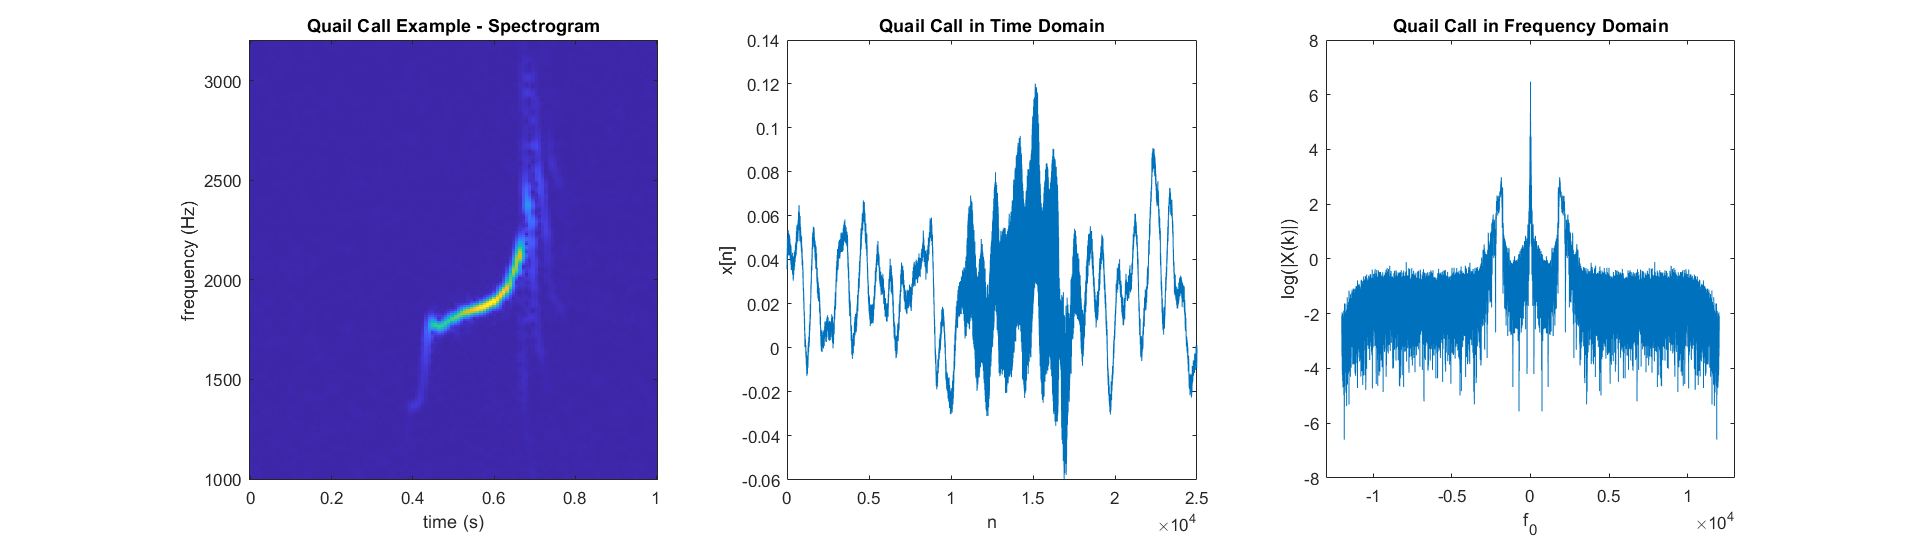

h = figure;

subplot(131);
image=spectrogram(quailCall,window,noverlap,F,fs);
imagesc(linspace(0,1,length(F)),F,abs(image))
ylabel('frequency (Hz)')
xlabel('time (s)')
set(gca,'YDir','normal')
title('Quail Call Example - Spectrogram')

subplot(132);
plot(quailCall)
xlabel('n')
ylabel('x[n]')
xlim([0 2.5e4])
title('Quail Call in Time Domain')
set(h,'Units','normalized','Position',[0 0 1 .5]); 

subplot(133);
fourierQuail = log(abs (fftshift(fft(quailCall))));             % Zero-Centered FFT
f0Quail = (-quailInfo.TotalSamples/2:quailInfo.TotalSamples/2-1)...
    /quailInfo.TotalSamples*fs;                                 % Zero-Centered Frequency Range
plot(f0Quail, fourierQuail)
ylabel('log(|X(k)|)')
xlabel('f_{0}');
xlim([-1.3e4 1.3e4])
title('Quail Call in Frequency Domain')

After inspecting the call in these plots, we concluded that even though the signature of the call is starting anywhere around the 1000-1500 Hz range up to 3200 Hz range, the main part of the call that we would like to preserve after filtering is between 1850 Hz to 2400 Hz. *(The yellow color in the spectrogram - This frequency range is what we hear and recogize as a "Quail Call" when listenning to the audio files)****.***

### Determining Bandwidth using $f_0$

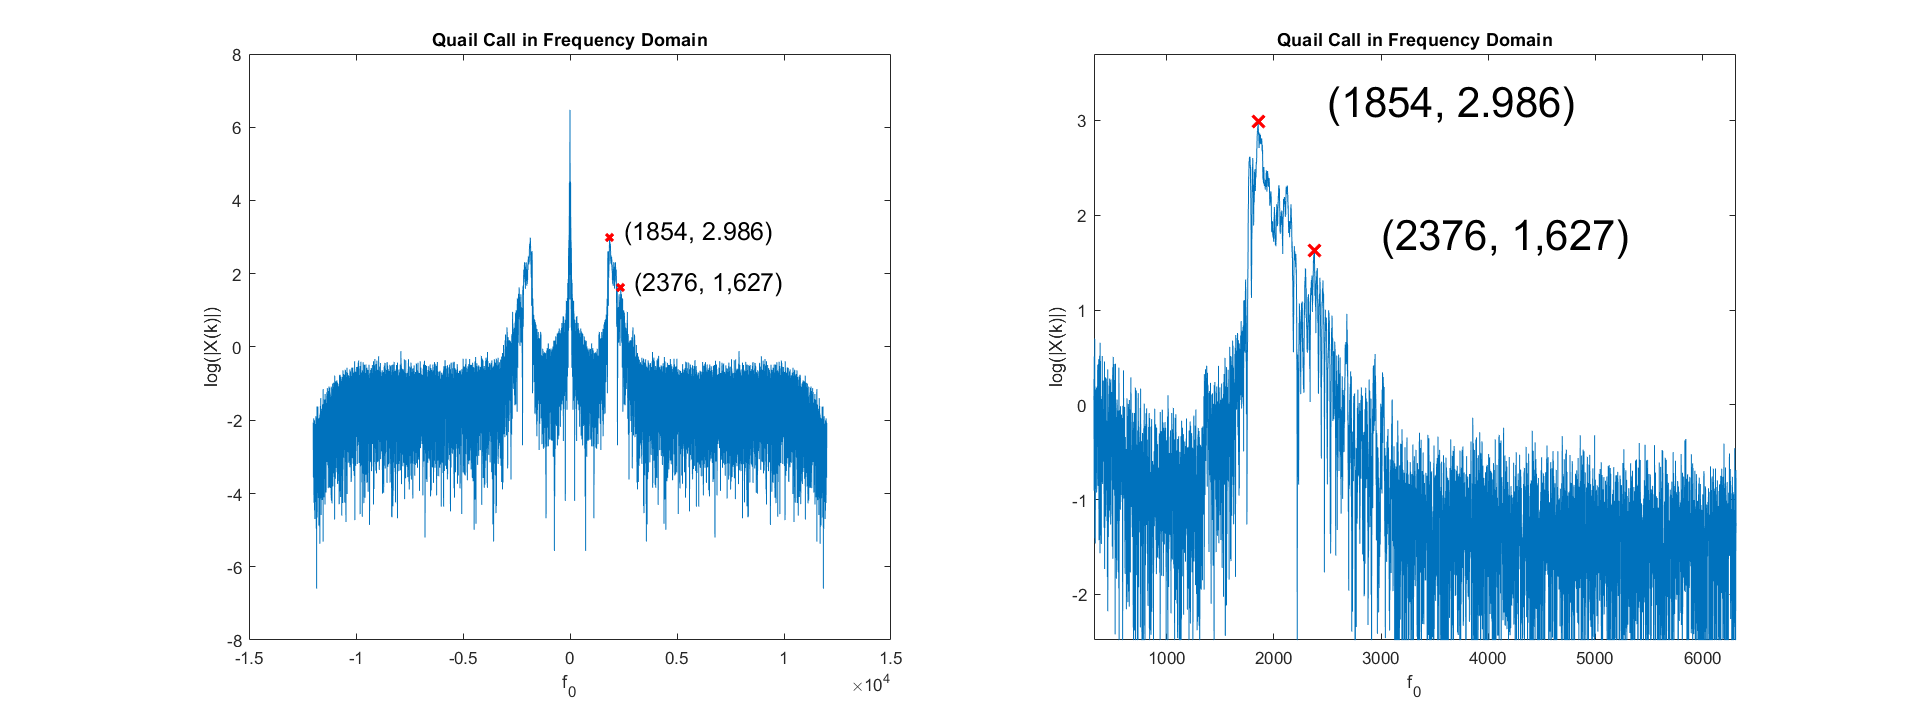

h = figure;
set(h,'Units','normalized','Position',[0 0 1.2 0.8]); 
subplot(121)
plot(f0Quail, fourierQuail)
ylabel('log(|X(k)|)')
xlabel('f_{0}');
title('Quail Call in Frequency Domain')
hold on
text(2500,3.2,['(' '1854' ',' ' 2.986' ')'], 'FontSize',15)
plot(1854,2.986,'rx','LineWidth',2)
text(3000,1.8,['(' '2376' ',' ' 1,627' ')'], 'FontSize',15)
plot(2376,1.627,'rx','LineWidth',2)
hold off
subplot(122)
plot(f0Quail, fourierQuail)
ylabel('log(|X(k)|)')
xlabel('f_{0}');
title('Quail Call in Frequency Domain')
hold on
text(2500,3.2,['(' '1854' ',' ' 2.986' ')'], 'FontSize',25)
plot(1854,2.986,'rx','LineWidth', 2, 'MarkerSize',10)
text(3000,1.8,['(' '2376' ',' ' 1,627' ')'], 'FontSize',25)
plot(2376,1.627,'rx','LineWidth', 2, 'MarkerSize',10)
xlim([322 6311])
ylim([-2.48 3.70])
hold off

We can see that our  $f_0 \;$range is approximately between $1854\;\textrm{Hz}$ to $2376\;\textrm{Hz}$ from the FFT graph.

This shows that our estimated range of 1850-2400 Hz could be potentially a good bandwidth for our filter.

### Filter Design

We started by designing several filter in the **Filter Designer **app.

After trying different 'Design Methods' we concluded that a **6th order Bandpass Butterworth **filter gives us the best results.

Here's a demonstration of our work:

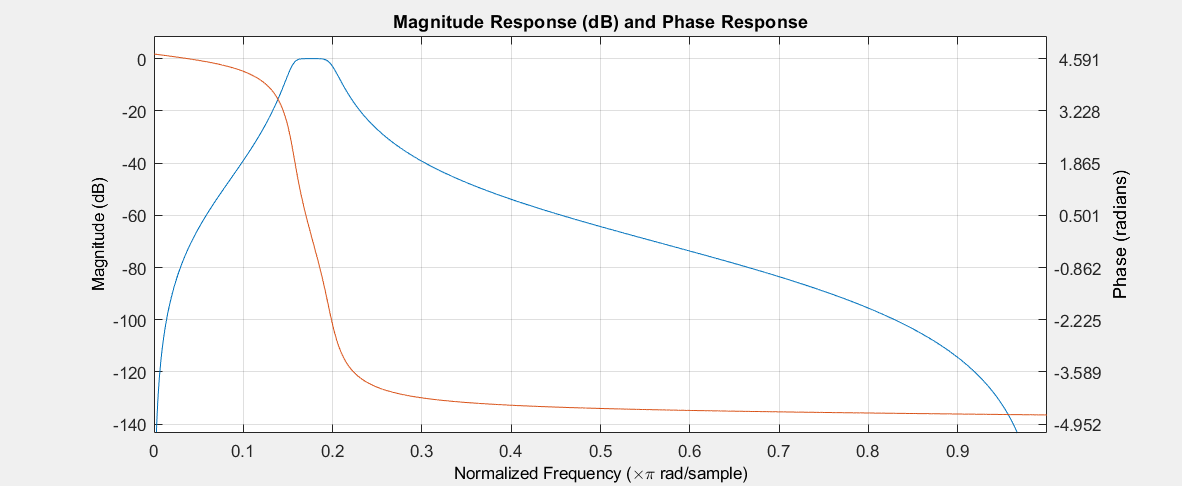

% Loading filter object from the designed filter
load('BPF_1850_2400.mat')
figure
freqz(BandpassFilter)

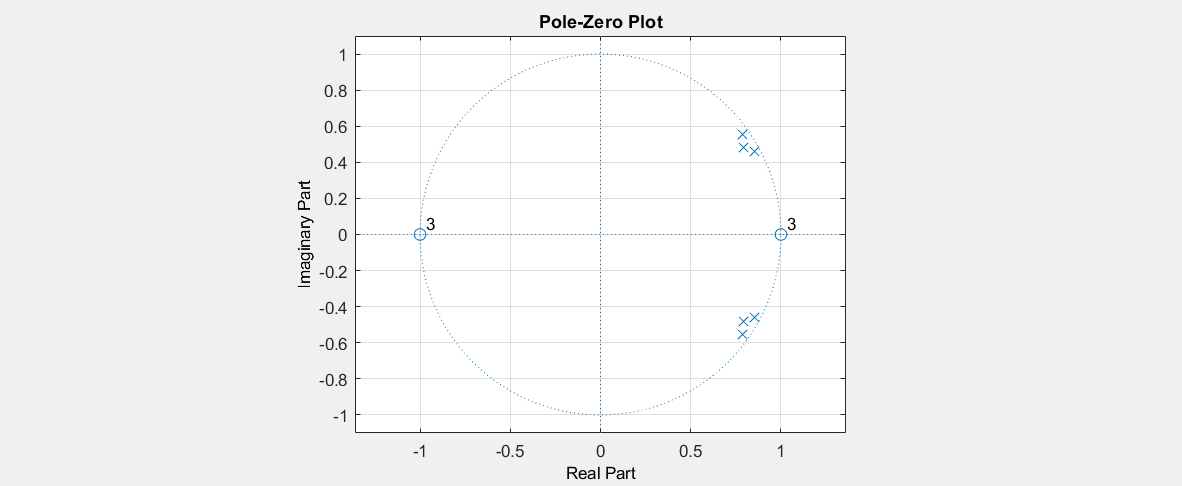

figure
zplane(BandpassFilter)

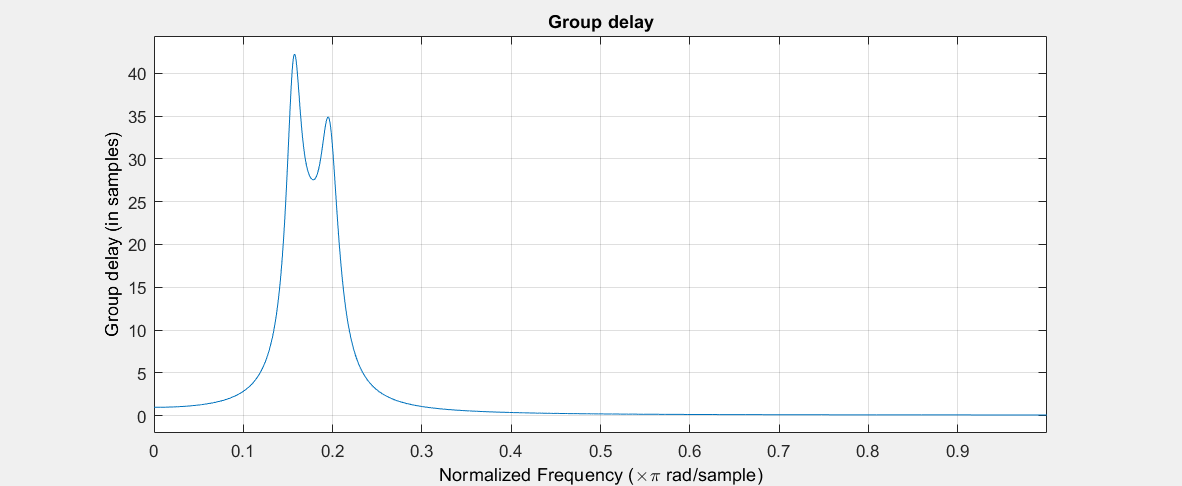

figure
grpdelay(BandpassFilter)

The two peaks in the figure above corresponds to frequencies 1886.7 Hz (left peak) and 2342.3 Hz (right peak). 

And the group delay for them is 1.76 ms and 1.453 ms respectively.

We will look at the group delay effect on the signal in the later sections.

% Filtering our signal
filteredSig = filter(BandpassFilter, noisySig);

### Resulting Signal in time Domain and Comparison with the Original Noisy Signal

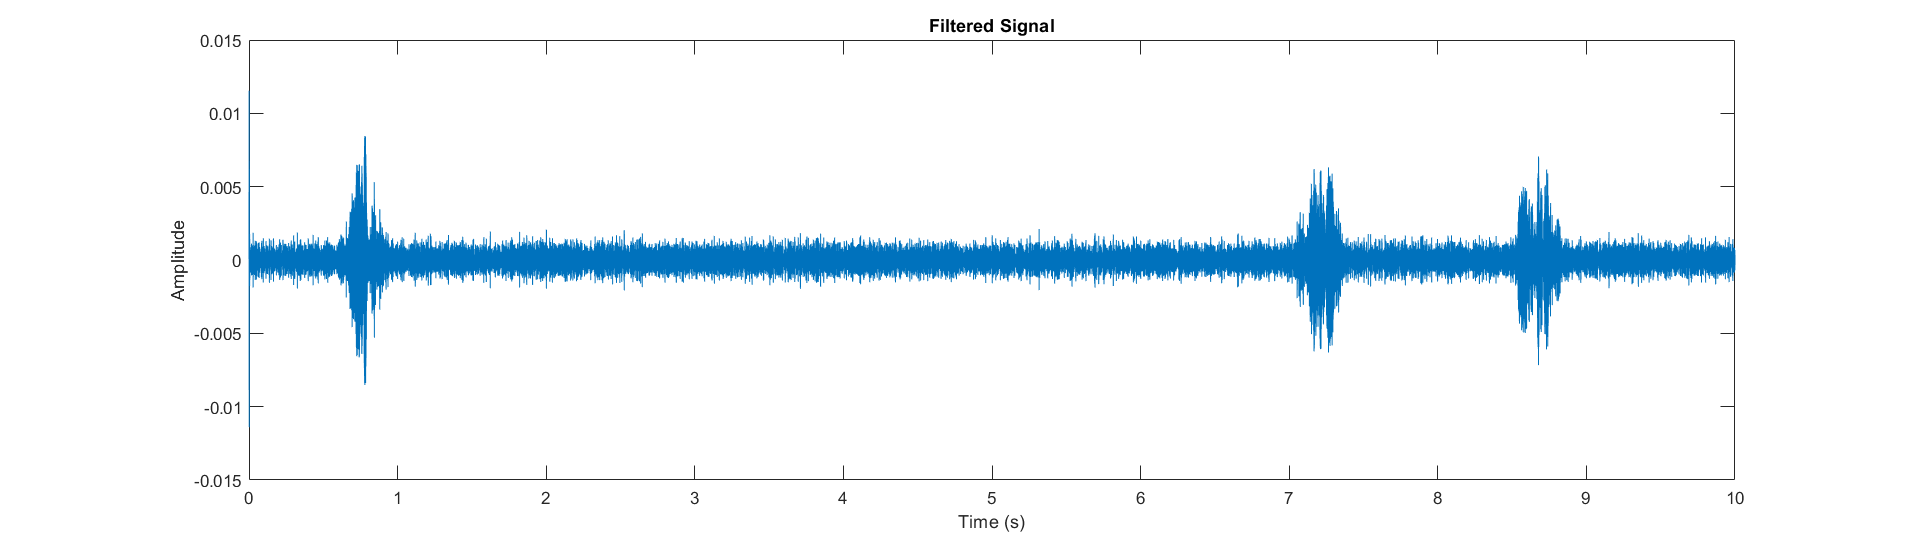

h = figure;
plot(timeNoisy, filteredSig)
title('Filtered Signal')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .5]);

Now we can clearly see the Call signatures in the Time Domain.

Let's compare the filtered signal with original noisy signal. Since the noisy signal has a DC offset, we need to plot it centering at zero so the comparison would be more valid.

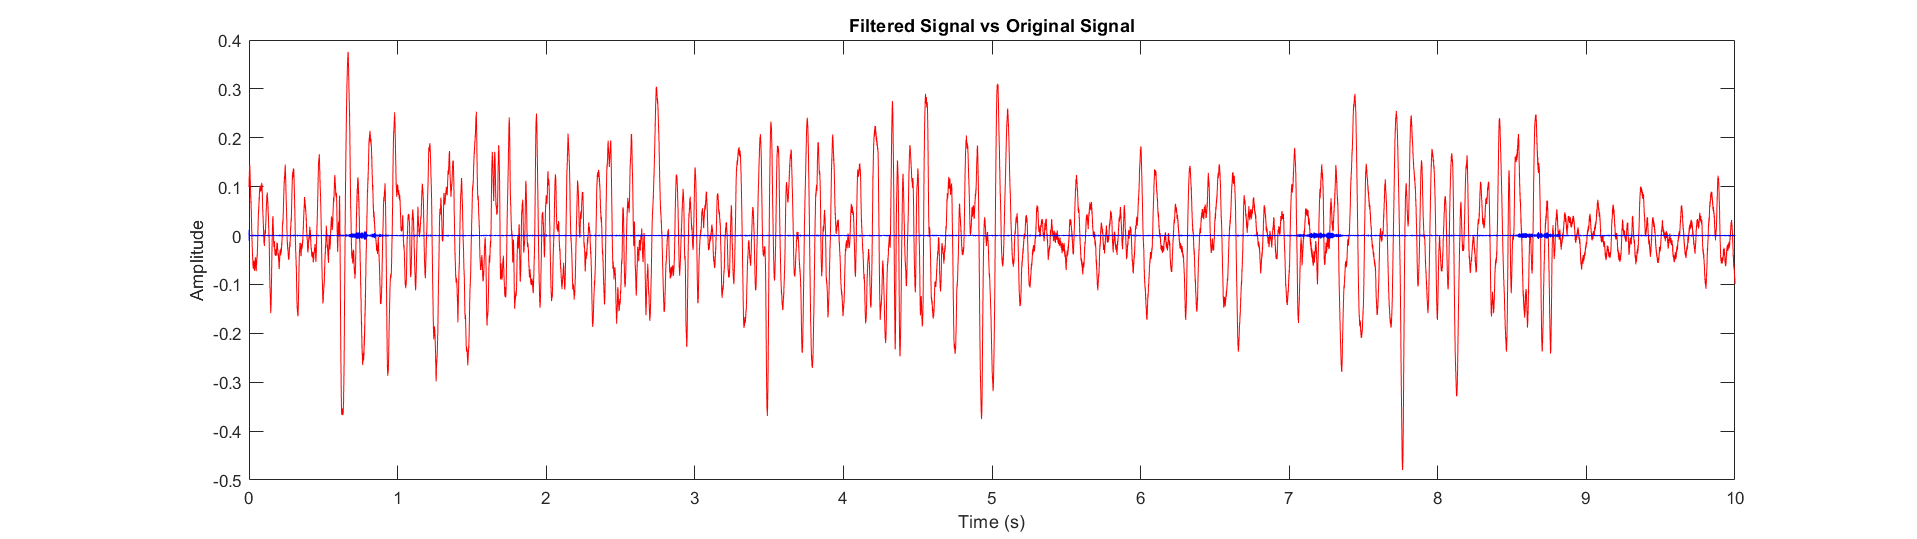

noisySig_zeroCentered = noisySig - mean(noisySig);      % Removing the DC offset
h = figure;
plot(timeNoisy, noisySig_zeroCentered, 'r')
hold on
plot(timeNoisy, filteredSig, 'b')
title('Filtered Signal vs Original Signal')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .5]);
legend("Original Noisy Signal", "Filtered Signal")
hold off

You can see how the calls' amplitude is so low with respect to the noise power. Again that's due to calls being far away from the microphones.

We will demonstrate this comparison again with the clean signal for clarification.

Lets listen to the resulting signal:

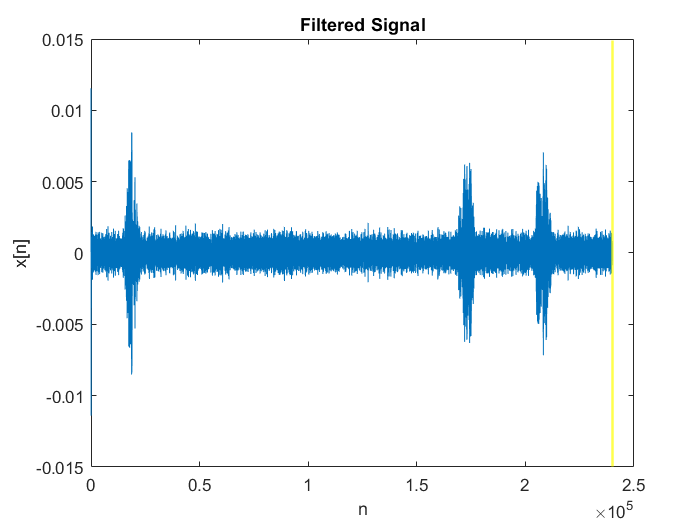

player3 = audioplayer(filteredSig,fs);
figure
plot(filteredSig)
title('Filtered Signal')
xlabel('n')
ylabel('x[n]')
pause(2)
hold on
Bar = xline(0,'Color','yellow','LineWidth',1.5);
play(player3);
for i = 1:length(filteredSig)/2400
     set(Bar,'Value',Bar.Value+2400);
     pause(.1);
end

audiowrite('resultSig.wav', filteredSig, fs)

### Resulting Signal in the Frequency Domain

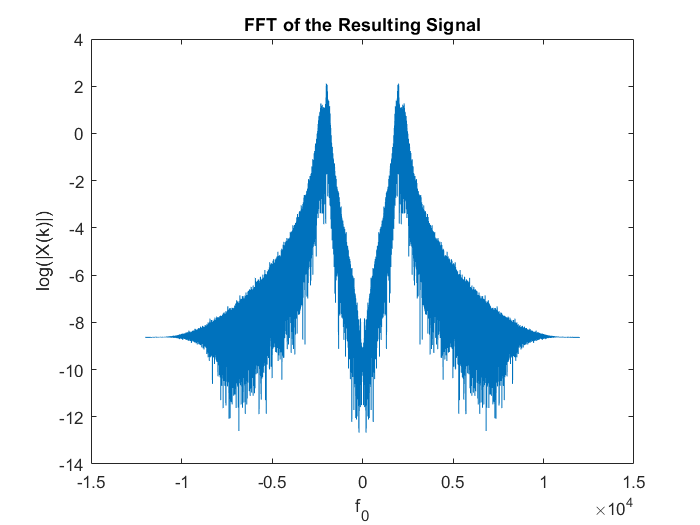

figure;
FFT = log(abs (fftshift(fft(filteredSig))));                  % Zero-Centered FFT
plot(f01, FFT)
title('FFT of the Resulting Signal');
ylabel('log(|X(k)|)')
xlabel('f_{0}');

### Applying the Filter to the Clean Signal Example and Comparing to the Original Clean Signal

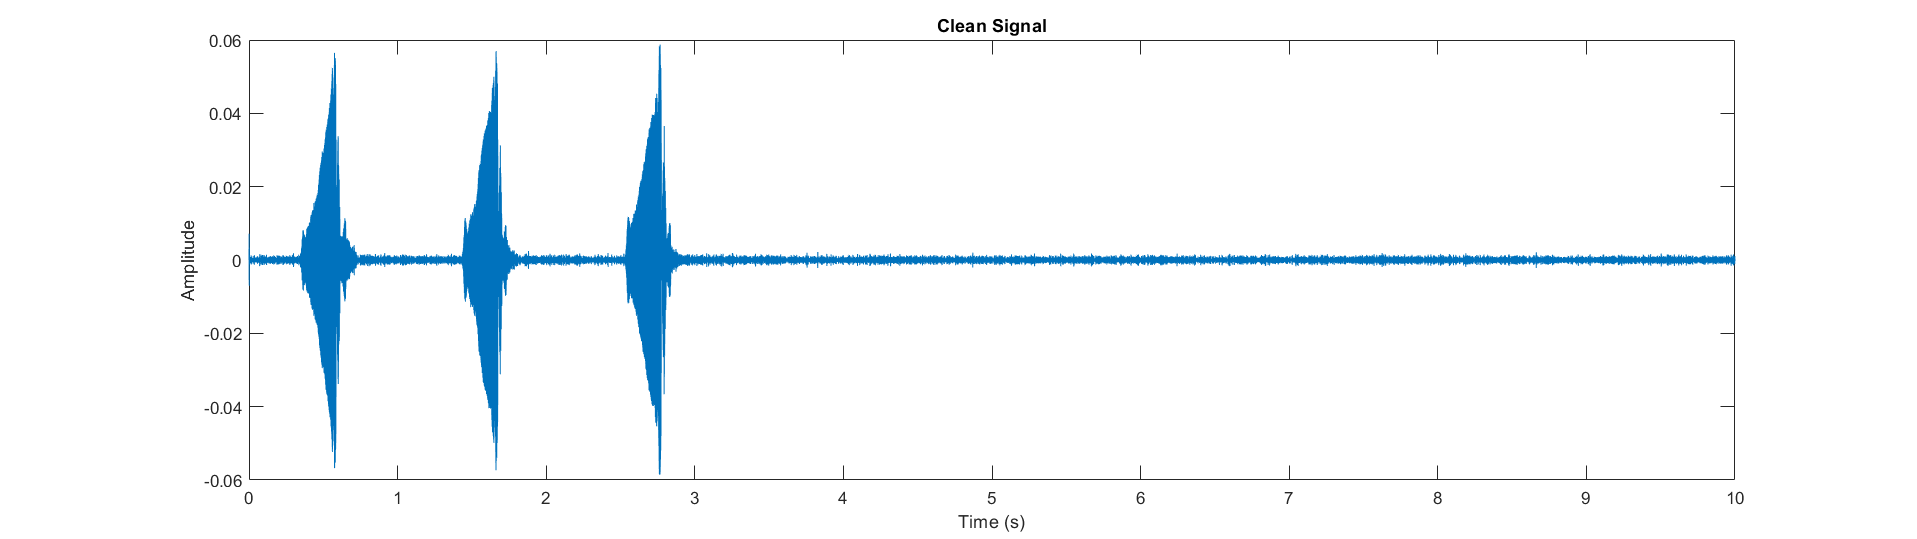

% Filtering
filteredSig2 = filter(BandpassFilter, cleanSig);

h = figure;
plot(timeClean, filteredSig2)
title('Filtered Clean Signal')
title('Clean Signal')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .5]);

Now lets compare the result to the original signal.

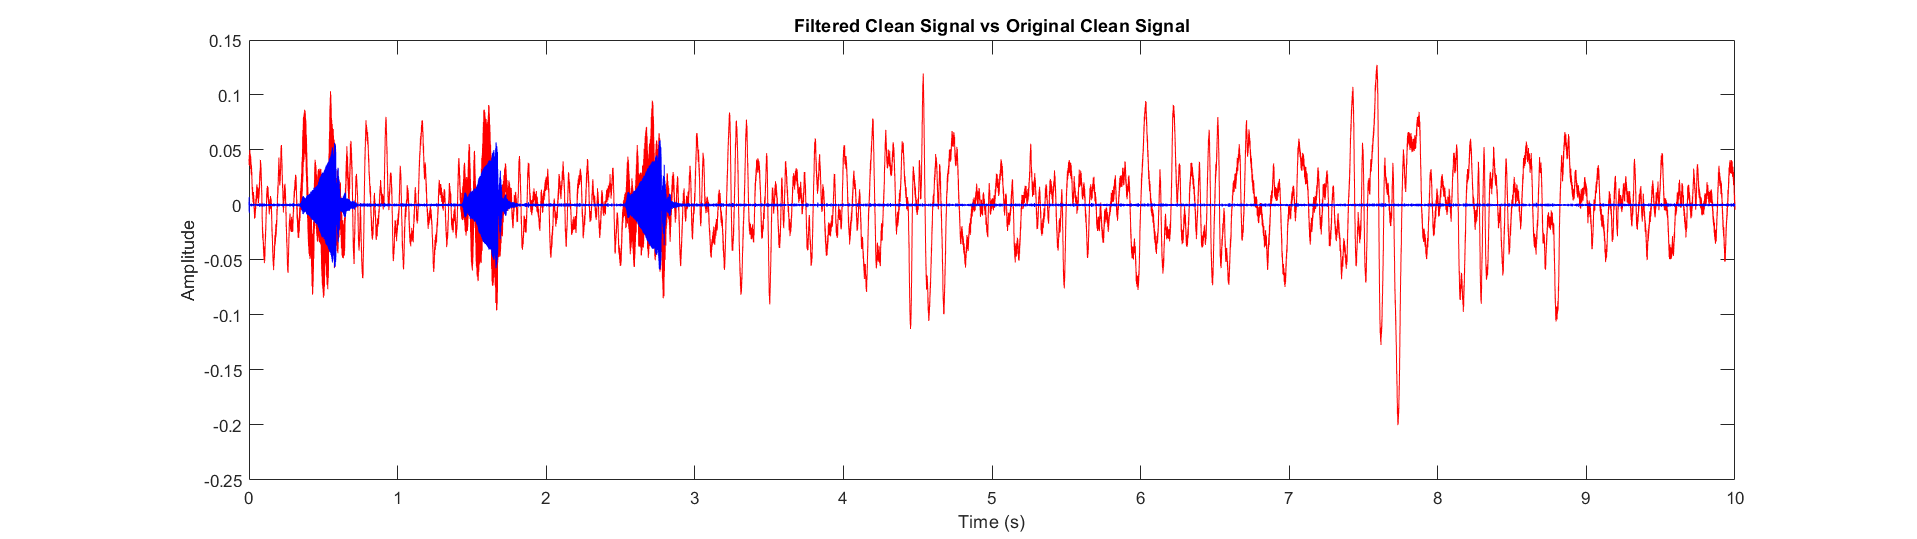

cleanSig_zeroCentered = cleanSig - mean(cleanSig);      % Removing the DC offset
h = figure;
plot(timeClean, cleanSig_zeroCentered, 'r')
hold on
plot(timeClean, filteredSig2, 'b')
title('Filtered Clean Signal vs Original Clean Signal')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .5]);
legend("Original Clean Signal", "Filtered Clean Signal")
hold off

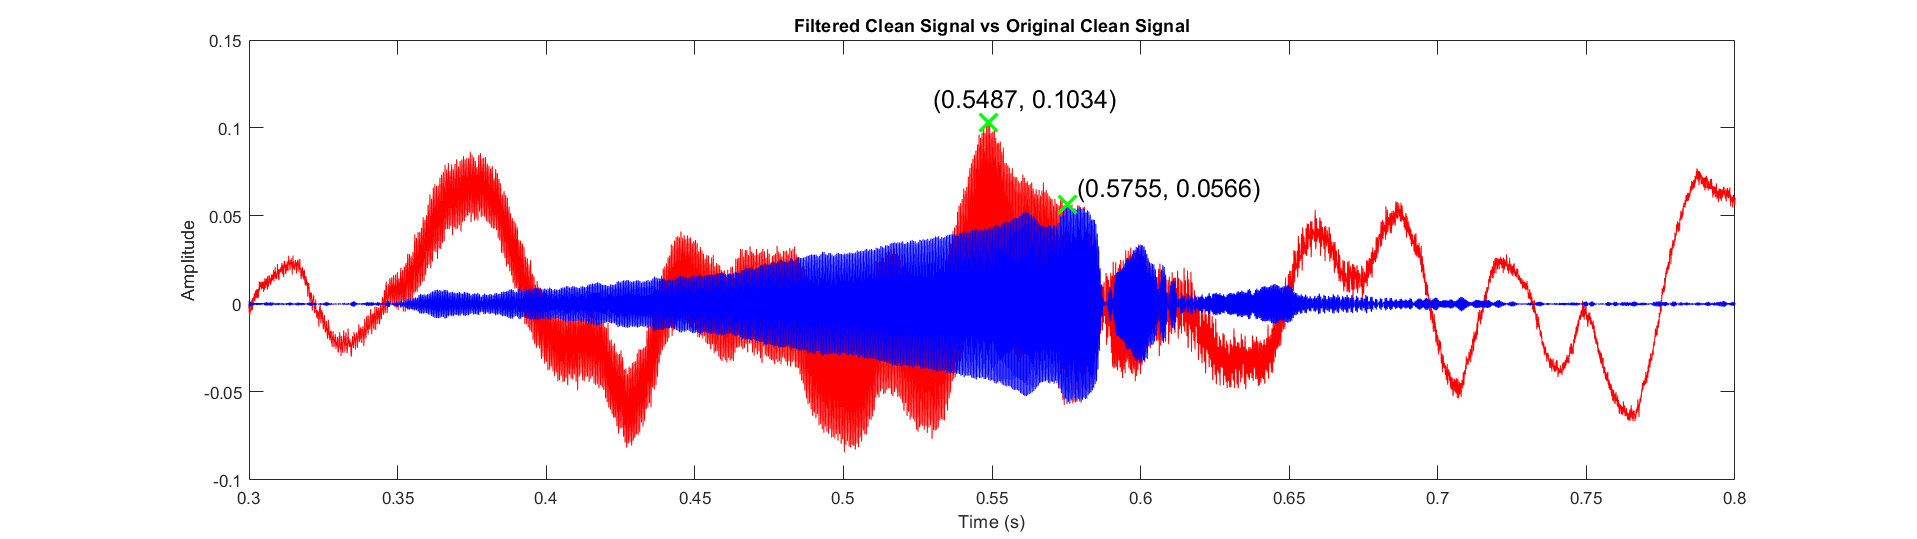

h = figure;
plot(timeClean, cleanSig_zeroCentered, 'r')
hold on
plot(timeClean, filteredSig2, 'b')
title('Filtered Clean Signal vs Original Clean Signal')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0.3 0.8])
set(h,'Units','normalized','Position',[0 0 1 .5]);
text(0.53,0.117,['(' '0.5487' ',' ' 0.1034' ')'], 'FontSize',15)
plot(0.5487,0.1034,'gx','LineWidth', 2, 'MarkerSize',15)
text(0.57855,0.0666,['(' '0.5755' ',' ' 0.0566' ')'], 'FontSize',15)
plot(0.5755,0.0566,'gx','LineWidth', 2, 'MarkerSize',15)
legend("Original Clean Signal", "Filtered Clean Signal")
hold off

If we look at the first call. We can see a time delay of around 30ms between the two peaks of the blue signal and red signal. 

And also you can see how the calls have higher amplitude in the clean signal after filtering unlike the noisy signal case. And this is again, because the quails were much closer to the microphone.

However, the small amount of time delay and the small amplitudes in the noisy signal shouldn't bother us as the ultimate goal of this project is to detect these calls in the Time-Domain which was something we couldn't do before especially in the case of noisy signals.

We will demostrate a simple quail call detection algorithm in the last section.

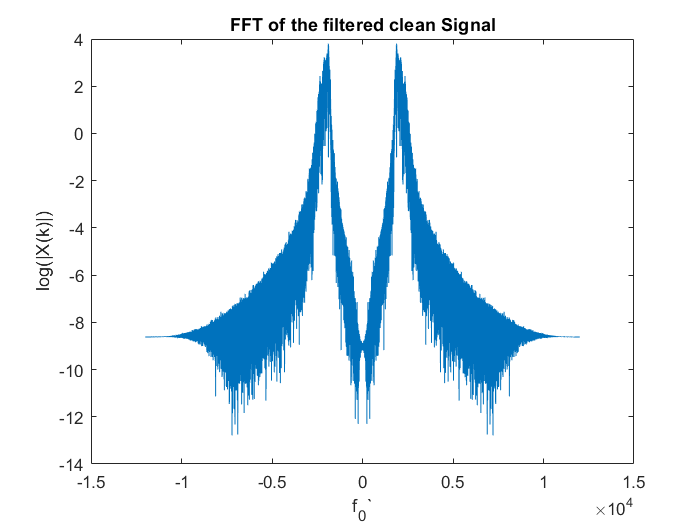

figure
FFT2 = log(abs (fftshift(fft(filteredSig2))));                  % Zero-Centered FFT
plot(f02, FFT2)
title('FFT of the filtered clean Signal');
ylabel('log(|X(k)|)')
xlabel('f_{0}`');

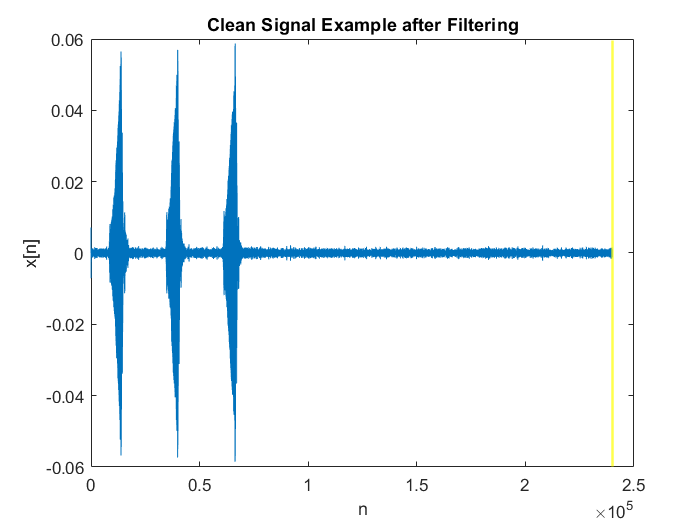

player4 = audioplayer(filteredSig2,fs);
figure
plot(filteredSig2)
xlabel('n')
ylabel('x[n]')
title('Clean Signal Example after Filtering')
pause(2)
hold on
Bar = xline(0,'Color','yellow','LineWidth',1.5);
play(player4);
for i = 1:length(filteredSig2)/2400 
     set(Bar,'Value',Bar.Value+2400);
     pause(.1);
end

audiowrite('resultSig_cleanSignalExample.wav', filteredSig2, fs);

We can see that, this filter can be applied to all the recordings whether the calls are far or close to the microphone. With this operation, the calls could be easily detected even just by looking at the Time-Domain signal plot.

### Simple Quail Call Detection Algorithm using Local Maxima of the Signal

As shown before, after reducing the noise from the background we can now clearly detect the calls just by inspecting the time-domain signal visually.

We can develop several algorithms to detect these calls which was one of the ultimate goals of this project.

Here's a simple algorithm that can detect these calls just using **Local Maxima:**

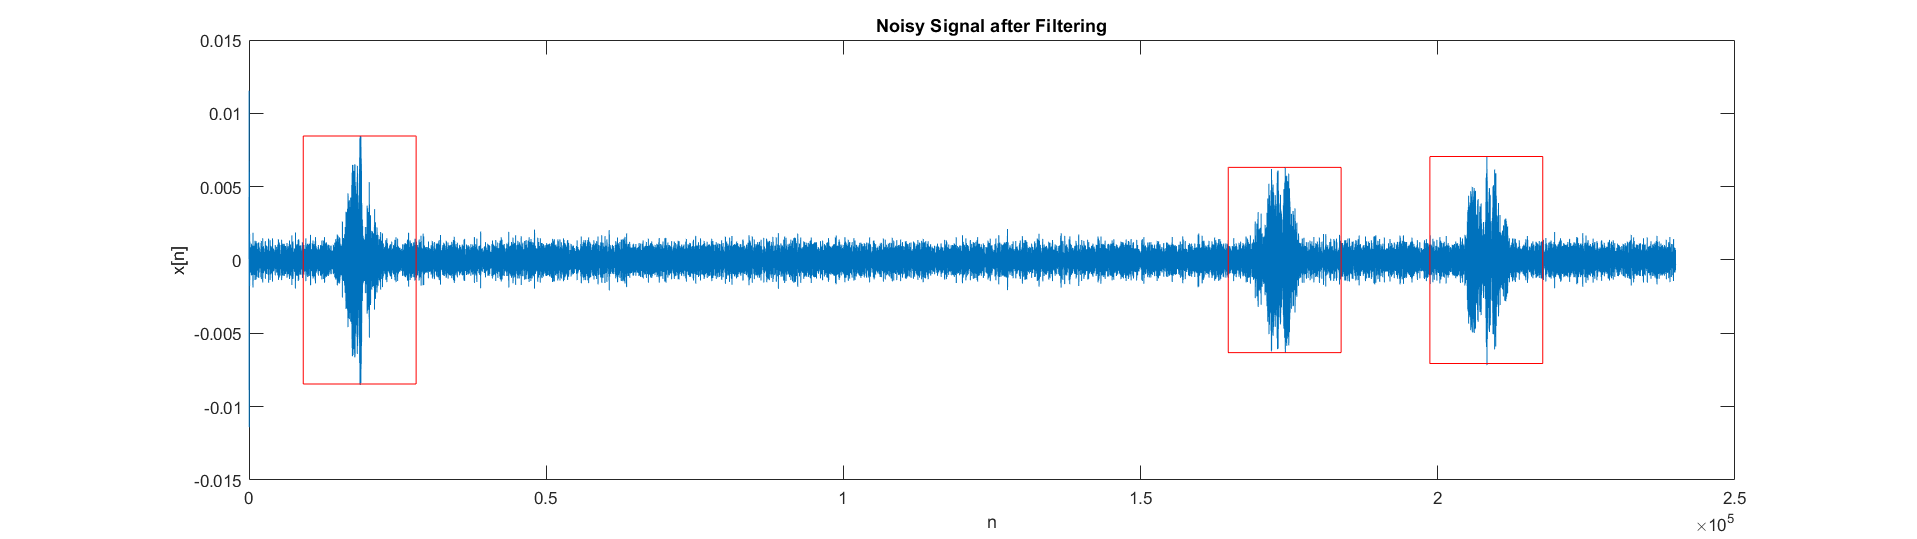

h = figure;
% Detecting Calls using Local Maxima
[pks, locs] = findpeaks(filteredSig(100:end), 'MinPeakProminence',0.01, 'MinPeakDistance', 10000);
plot(filteredSig)
title('Noisy Signal after Filtering')
xlabel('n')
ylabel('x[n]')
for i = 1:length(pks)
    rectangle('Position', [locs(i)-9500 -pks(i) 19000 2*pks(i)], 'EdgeColor', 'r')
end
set(h,'Units','normalized','Position',[0 0 1 .5]);

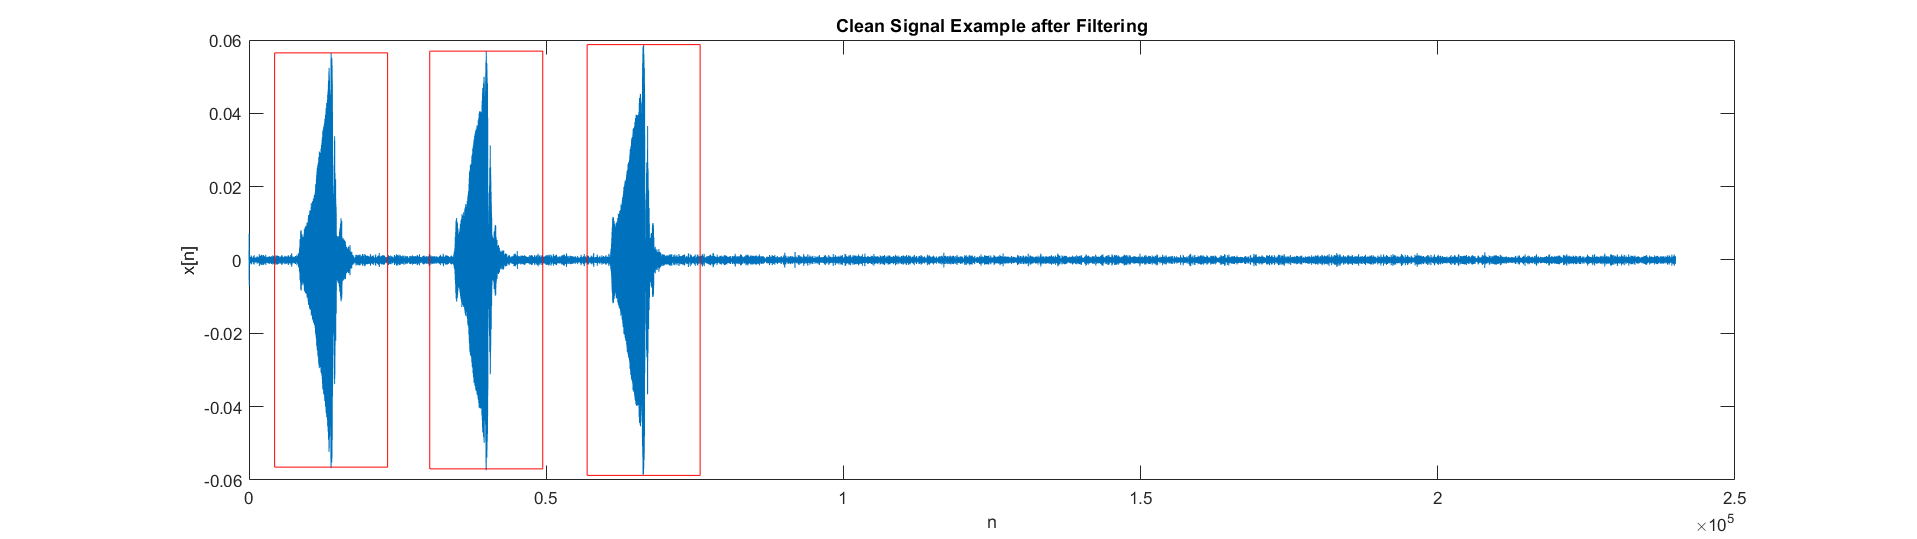


h = figure;
% Detecting Calls using Local Maxima
[pks2, locs2] = findpeaks(filteredSig2, 'MinPeakProminence',0.1, 'MinPeakDistance', 1000);
plot(filteredSig2)
xlabel('n')
ylabel('x[n]')
title('Clean Signal Example after Filtering')
for i = 1:length(pks2)
    rectangle('Position', [locs2(i)-9500 -pks2(i) 19000 2*pks2(i)], 'EdgeColor', 'r')
end
set(h,'Units','normalized','Position',[0 0 1 .5]);

### References

- Karp, Tanja. Physical Frequency Equation and Notch Filter.

- MATLAB Documentation. Fast Fourier Transform. [https://www.mathworks.com/help/matlab/ref/fft.html?s_tid=doc_ta](https://www.mathworks.com/help/matlab/ref/fft.html?s_tid=doc_ta). 

- MATLAB Documentation. Filter. [https://www.mathworks.com/help/matlab/ref/filter.html?s_tid=doc_ta](https://www.mathworks.com/help/matlab/ref/filter.html?s_tid=doc_ta). 

- MATLAB Documentation. filterDesigner. [https://www.mathworks.com/help/dsp/ref/filterdesigner.html?s_tid=doc_ta](https://www.mathworks.com/help/dsp/ref/filterdesigner.html?s_tid=doc_ta). 

- MATLAB Documentation. Findpeaks. [https://www.mathworks.com/help/signal/ref/findpeaks.html](https://www.mathworks.com/help/signal/ref/findpeaks.html). 

- MATLAB Documentation. Spectrogram. [https://www.mathworks.com/help/signal/ref/spectrogram.html?s_tid=doc_ta](https://www.mathworks.com/help/signal/ref/spectrogram.html?s_tid=doc_ta). 

- Sari-Sarraf, Hamed. Additive Noise Model and Call Detection.